% select input points
t = 0 : 0.1 : 10;

% fix the mean of the prior
Mean = zeros(numel(t),1);

% calculate the covariance matrix (squared exponential)
Sigma = exp(-1/2 * ( meshgrid(t,ones(1,numel(t)))-meshgrid(t,ones(1,numel(t)))' ).^2);

% extract points from a multivariate gaussian
R1 = mvnrnd(Mean,Sigma);
R2 = mvnrnd(Mean,Sigma);
R3 = mvnrnd(Mean,Sigma);


## Plot prior

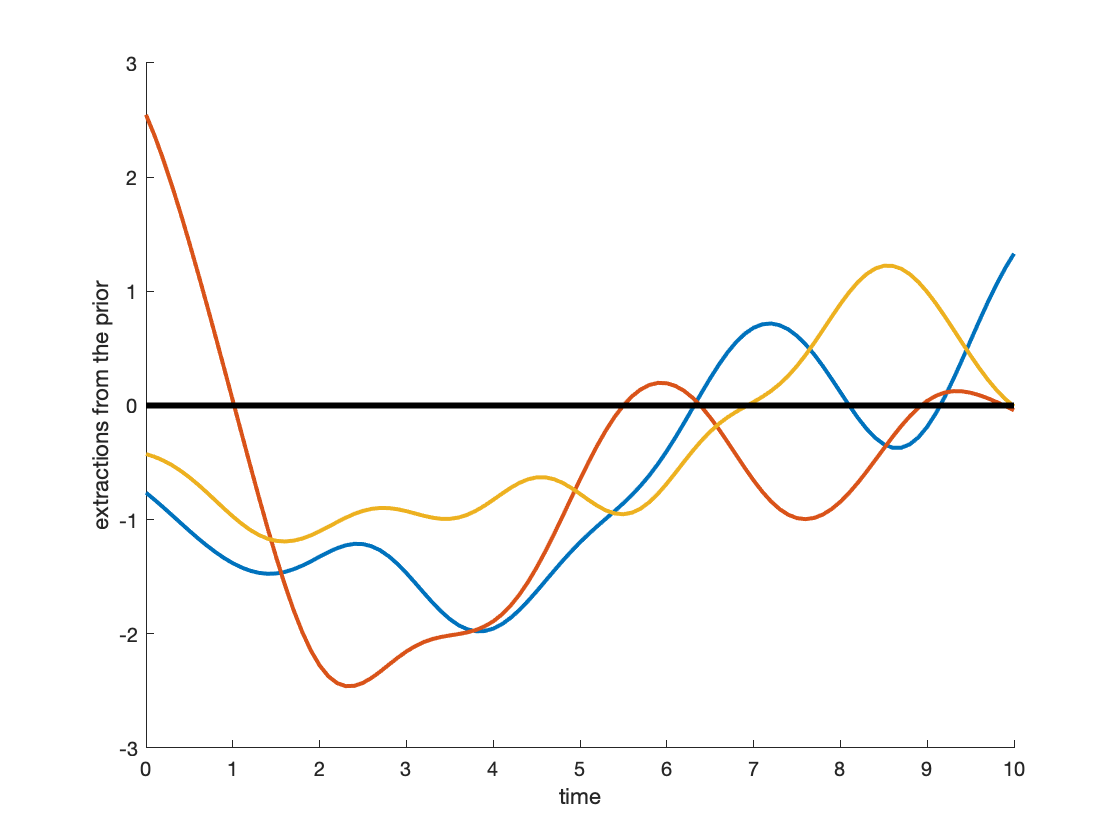

figure
hold on

plot(t, R1, 'LineWidth', 2)
plot(t, R2, 'LineWidth', 2)
plot(t, R3, 'LineWidth', 2)
plot(t, Mean, 'k', 'LineWidth', 3)

xlabel('time')
ylabel('extractions from the prior')